**Miniproyecto 1**

**Por: Julian Sanchez Ceballos, Yonathan Lopez Mejia**

**Nota: **Faltan tildes en el notebook, esto se debe a que ML no las reconoce.

Las coordenadas de cada masa son:

Para $$m$$ la posición viene dada por $$(x,0)$$ y la velocidad por $$(\dot{x},0)$$

Para $$m_{1}$$ la posición viene dada por $$(x+L_{1}sin(\theta_{1}), L_{1}cos(\theta_{1}))$$ y la velocidad $$(\dot{x}+L_{1}\dot{\theta_{1}}cos(\theta_{1}), -L_{1}\dot{\theta_{1}}sin(\theta_{1}))$$

Para $$m_{2}$$ la posición viene dada por $$(x+L_{1}sin(\theta_{1}) + L_{2}sin(\theta_2), L_{1}cos(\theta_{1}) + L_{2}cos(\theta_{2}))$$ y su velocidad se puede expresar como: $$(\dot{x}+L_{1}\dot{\theta_{1}}cos(\theta_{1}) + L_{2}\dot{\theta_{2}}cos(\theta_2), -L_{1}\dot{\theta_{1}}sin(\theta_{1}) - L_{2}\dot{\theta_{2}}sin(\theta_{2}))$$

De manera similar, la energía potencial del sistema es $$E_{p} = m_{1}gL_{1}cos(\theta_{1}) + m_{2}g(L_{1}cos(\theta_{1}) + L_{2}cos(\theta_{2}))$$.

clear all
clc
syms x1 x1d x1dd x2 x2d x2dd x3 x3d x3dd real;
syms f0 real;

Luego definimos nuestra variables, las coordenadas de posición y sus respectivas velocidades.

syms m m1 m2 j1 j2 L1 L2 g real;

% x1 = x
% x2 = theta1
% x3 = theta2

% Coordenadas masa m del carrito
px1 = x1;
py1 = 0;

px2 = x1 + L1*sin(x2);
py2 = L1*cos(x2);

px3 = px2 + L2*sin(x3);
py3 = py2 + L2*cos(x3);

vx1 = x1d;
vy1 = 0;
vx2 = vx1 + L1*cos(x2)*(x2d);
vy2 = -L1*sin(x2)*(x2d);
vx3 = vx2 + L2*cos(x3)*(x3d);
vy3 = vy2 - L2*sin(x3)*(x3d); 

Ahora para la energía cinética y potencial del sistema:

KE = 0.5*m*vx1^2 + 0.5*j1*x2d^2 + 0.5*m1*(vx2^2 + vy2^2) + 0.5*j2*x3d^2 + 0.5*m2*(vx3^2 + vy3^2);
KE = simplify(KE)

$$KE = \frac{m_{2}\,\left({\left(\mathrm{x1d}+L_{1}\,\mathrm{x2d}\,\cos\left(x_{2}\right)+L_{2}\,\mathrm{x3d}\,\cos\left(x_{3}\right)\right)}^{2}+{\left(L_{1}\,\mathrm{x2d}\,\sin\left(x_{2}\right)+L_{2}\,\mathrm{x3d}\,\sin\left(x_{3}\right)\right)}^{2}\right)}{2}+\frac{m_{1}\,\left({L_{1}}^{2}\,{\mathrm{x2d}}^{2}+2\,\cos\left(x_{2}\right)\,L_{1}\,\mathrm{x1d}\,\mathrm{x2d}+{\mathrm{x1d}}^{2}\right)}{2}+\frac{j_{1}\,{\mathrm{x2d}}^{2}}{2}+\frac{j_{2}\,{\mathrm{x3d}}^{2}}{2}+\frac{m\,{\mathrm{x1d}}^{2}}{2}$$


PE = m1*g*L1*cos(x2) + m2*g*(L1*cos(x2) + L2*cos(x3));
PE = simplify(PE)

$$PE = g\,m_{2}\,\left(L_{1}\,\cos\left(x_{2}\right)+L_{2}\,\cos\left(x_{3}\right)\right)+L_{1}\,g\,m_{1}\,\cos\left(x_{2}\right)$$


Px1= f0;
Px2 = 0;
Px3 = 0;

A partir de estas energías implementamos el formalismo Lagrangiano

Fifth, solve the Lagrangian equation

We have to get the Lagrangian eqn. $$\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}_j}\right)-\frac{\partial T}{\partial q_j}+\frac{\partial V}{\partial q_j}=P_j$$

Let's obtain step by step.

$$\left(\frac{\partial T}{\partial \dot{q}}\right)}$$ is obtained by 

*pKEpx1d = diff(KE, x1d);*

To calculate, $$\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}}\right)$$, we need the chain rule, that is


$$$$
\frac{d}{d t}\left(\frac{\partial T}{\partial \dot{q}_j}\right)=\sum_i^3\left\{\frac{\partial}{\partial q_i}\left(\frac{\partial T}{\partial \dot{q}_j}\right) \frac{d q_i}{d t}+\frac{\partial}{\partial \dot{q}_i}\left(\frac{\partial T}{\partial q_j}\right) \frac{d \dot{q}_i}{d t}\right\}
$$$$


*ddtpKEpx1d = diff(pKEpx1d,x1)x1d+ …*

*diff(pKEpx1d,x1d)*

*x1dd+ …*

*diff(pKEpx1d,x2)x2d + …*

*diff(pKEpx1d,x2d)*

*x2dd + …*

*diff(pKEpx1d,x3)x3d + …*

*diff(pKEpx1d,x3d)*

*x3dd;*

$$\frac{\partial T}{\partial q_j}, \frac{\partial V}{\partial q_j}$$ are easily obtained by

*pKEpx1 = diff(KE,x1);*

*pPEpx1 = diff(PE,x1);*

pKEpx1d = diff(KE,x1d);
ddtpKEpx1d = diff(pKEpx1d,x1)*x1d+ ...
             diff(pKEpx1d,x1d)*x1dd+ ...
             diff(pKEpx1d,x2)*x2d + ...
             diff(pKEpx1d,x2d)*x2dd + ...
             diff(pKEpx1d,x3)*x3d + ...
             diff(pKEpx1d,x3d)*x3dd;

pKEpx1 = diff(KE,x1);
pPEpx1 = diff(PE,x1);


pKEpx2d = diff(KE,x2d);
ddtpKEpx2d = diff(pKEpx2d,x1)*x1d+ ...
             diff(pKEpx2d,x1d)*x1dd+ ...
             diff(pKEpx2d,x2)*x2d + ...
             diff(pKEpx2d,x2d)*x2dd + ...
             diff(pKEpx2d,x3)*x3d + ...
             diff(pKEpx2d,x3d)*x3dd;
pKEpx2 = diff(KE,x2);
pPEpx2 = diff(PE,x2);

pKEpx3d = diff(KE,x3d);
ddtpKEpx3d = diff(pKEpx3d,x1)*x1d+ ...
             diff(pKEpx3d,x1d)*x1dd+ ...
             diff(pKEpx3d,x2)*x2d + ...
             diff(pKEpx3d,x2d)*x2dd + ...
             diff(pKEpx3d,x3)*x3d + ...
             diff(pKEpx3d,x3d)*x3dd;
pKEpx3 = diff(KE,x3);
pPEpx3 = diff(PE,x3);

eqx1 = simplify( ddtpKEpx1d - pKEpx1 + pPEpx1 - Px1);
eqx2 = simplify( ddtpKEpx2d - pKEpx2 + pPEpx2 - Px2);
eqx3 = simplify( ddtpKEpx3d - pKEpx3 + pPEpx3 - Px3);

Ahora solucionamos para los términos $\ddot{x}\quad \ddot{\theta_{1}}\quad\text{y}\quad\ddot{\theta_{2}}$

Sol = solve([eqx1,eqx2,eqx3],[x1dd,x2dd,x3dd]);
Sol.x1dd = simplify(Sol.x1dd);
Sol.x2dd = simplify(Sol.x2dd);
Sol.x3dd = simplify(Sol.x3dd);

syms y1 y2 y3 y4 y5 y6
fx1 = y2

$$fx1 = y_{2}$$

fx2=subs(Sol.x1dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})

fx3 = y4

$$fx3 = y_{4}$$

fx4=subs(Sol.x2dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})

fx5 = y6

$$fx5 = y_{6}$$

fx6 = subs(Sol.x3dd,{x1,x1d,x2,x2d,x3,x3d},{y1,y2,y3,y4,y5,y6})


F = [fx1;fx2;fx3;fx4;fx5;fx6]

Linealizando el sistema utilizando el jacobiano

% jacobian
A_symbolic = jacobian(F, [y1,y2,y3,y4,y5,y6])

B_symbolic = jacobian(F, f0);

Evaluando en los puntos de equilibrio

m_c = 1.5

m_c = 1.5000

m_1 = 0.4

m_1 = 0.4000

m_2 = 0.4

m_2 = 0.4000

g_ = 9.81

g_ = 9.8100

l_1 = 0.6

l_1 = 0.6000

l_2 = 0.6

l_2 = 0.6000

j_1 = 0.012

j_1 = 0.0120

j_2 = 0.012

j_2 = 0.0120

% matrices A, B, C, D

A_algebraic = simplify(subs(A_symbolic, {m m1 m2 g L1 L2 j1 j2 y1 y2 y3 y4 y5 y6 f0}, ...
                [sym(m_c) sym(m_1) sym(m_2) sym(g_) sym(l_1) sym(l_2) sym(j_1) sym(j_2) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0.5)]));
B_algebraic = simplify(subs(B_symbolic, {m m1 m2 g L1 L2 j1 j2 y1 y2 y3 y4 y5 y6 f0}, ...
                [sym(m_c) sym(m_1) sym(m_2) sym(g_) sym(l_1) sym(l_2) sym(j_1) sym(j_2) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0) sym(0.5)]));

Calculando las expresiones numericas

% compute numerical values            
A_eval = eval(A_algebraic);
B_eval = eval(B_algebraic);

Ahora se puede crear el espacio de estados, supongamos que se puede medir $x$, $\theta_{1}$ y $\theta_{2}$

C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];

D = [0; 0; 0];

sysLTI = ss(A_eval,B_eval,C,D)

sysLTI =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        1        0        0        0        0
   x2        0        0   -4.758        0  -0.1699        0
   x3        0        0        0        1        0        0
   x4        0        0    35.54        0   -12.74        0
   x5        0        0        0        0        0        1
   x6        0        0   -25.49        0    27.12        0
 
  B = 
             u1
   x1         0
   x2    0.6532
   x3         0
   x4     -1.01
   x5         0
   x6  -0.07218
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
   y3   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


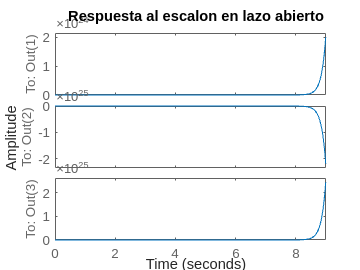

step(sysLTI);
title("Respuesta al escalon en lazo abierto");

De las graficas se observa que el sistema es inestable y rapidamente las posiciones del carrito y los dos brazos convergen al infinito. Este hecho tambien se observa al tener dos polos a la derecha en y otros dos en cero.

eig(A_eval)

ans =          0
         0
   -7.0598
   -3.5807
    7.0598
    3.5807


**3.a. Control por realimentacion de estados:** Supongamos que se quiere un sobreimpulso de 0.01 y un tiempo de establecimiento de 5 segundos. Los dos polos deseados se calculan como sigue y los demas son mas pequeños que el menor polo en lazo abierto. (Ver sm_mp1_re.slx)

Mp = 0.01;
Ts = 5;
e=sqrt(((log(Mp))^2)/(((log(Mp))^2)+pi^2));
wn=4.6/(Ts*e);
polo_des_2do = roots([1 2*e*wn wn^2]);
polos_des = [polo_des_2do(1) polo_des_2do(2) -8 -9 -10 -11];
k = acker(A_eval, B_eval, polos_des);

Ahora, se observa como el control por realimentacion de estados fue efectivo al momento de controlar todo el sistema.

**4. El sistema discretizado. **El tiempo de muestreo maximo debera calcularse con el polo de mayor  valor absoluto. Luego de aplicar eig(A_eval) se obtiene que dicho polo esta en: -7.0598. Se observa que la discretizacion no es lo suficientemente suave. Se puede disminuir a un cuarto el tiempo de muestreo:

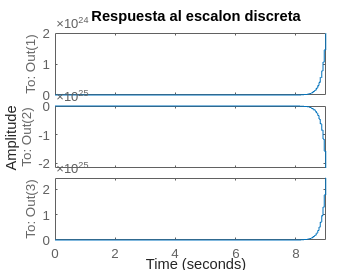

tm = (2*pi)/(20*7.0598);
G_dis = c2d(sysLTI, tm);
figure(1)
step(G_dis);
title("Respuesta al escalon discreta");

La nueva grafica se puede obtener como: 

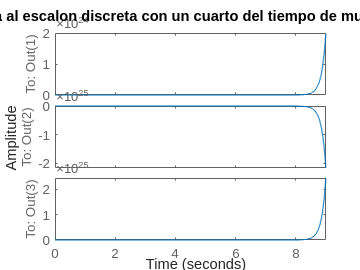

tm = (2*pi)/(4*20*7.0598);
G_dis = c2d(sysLTI, tm);
figure(1)
step(G_dis);
title("Respuesta al escalon discreta con un cuarto del tiempo de muestreo original");

**5. Calcule un control+observador por realimentación de estados discreto u[k]=-kx[k] el cual lleve las variables de estado desde una condición inicial (cercana a los puntos de equilibrio “ángulos pequeños”) a los puntos de equilibrio del sistema.**

Pero, antes, ¿el sistema continuo es controlable? La matriz de controlabilidad o la matriz de observabilidad deberan ser de rango completo o 6 (pues hay 6 estados)

rank(ctrb(A_eval, B_eval)) %Controlabilidad

ans = 6

rank(obsv(A_eval, [1 0 0 0 0 0])) %Supongamos que solamente se puede observar el movimiento del carrito

ans = 6

Y por tanto, el sistema es observable y controlable. Ahora se procede a calcular los parametros para el observador discreto a partir de parametros del sistema continuo

%Encontremos la K para el sistema discreto
polos_des_dis = exp(polos_des*tm);
%Los polos del observador deben ser minimo 5 veces mas rapidos que los de
%la planta
polos_obs_des = [-100, -101, -102, -103, -104, -105];
polos_obs_des_dis = exp(polos_des*tm);
%La matriz de estados discreta
A_dis = G_dis.A;
B_dis = G_dis.B;
C_dis = [1 0 0 0 0 0];
k_dis = place(A_dis, B_dis, polos_des_dis);
L_dis = place(A_dis',C_dis',polos_obs_des_dis);
L_dis = L_dis.';

En el archivo sm_obs_dis.slxc se puede acceder al diagrama de bloques que implementa el control con observador discreto. 

Si se mira en el scope correspodiente es claro que se controlaron los 6 estados y el sistema ahora es estable. El error en estado estacionario mas grande no alcanza el 1%.

**Realice simulaciones en Python, SIMSCAPE del péndulo doble MATLAB y verifique su**

**funcionamiento en el ambiente 3D. Discuta al respecto.**

En SIMSCAPE se realizo la simulacion a partir del tutorial facilitado por el docente, para agregar el segundo brazo se agrego un puerto R al bloque del pendulo y a partir de el se agregaron los demas componentes. No fue necesario hacer cambios en el control PID dado en el tutorial y el sistema permanecio estable, se observa una pequeña perturbacion casi al final de la simulacion en 3D pero inmediatamente despues el sistema vuelve a estabilizarse. En Python se hicieron algunas simulaciones del sistema continuo y discreto en lazo abierto, del lugar de las raices de la planta y de un control por realimentacion de estados, los resultados son identicos a los aca mostrados. Como no deberia ser de otra forma.

**Conclusiones**

    El control PID es una forma sencilla y empirica de controlar un sistema pero precisamente por eso se muestra limitado cuando el sistema se hace complejo y comienza a tener multiples entradas o multiples salidas, ademas, si la dinamica del sistema es compleja este tipo de control tambien se muestra limitado y para estas situaciones existen otras formas de control como el control por realimentacion de estados o con observador los cuales son mucho mas potentes que el PID.

El control digital, al menos en este primer acercamiento, comparte muchas estrategias de control con el continuo haciendo que toda la teoria desarrollada y aplicada en sistemas continuos sea completamente aplicable en un mundo como el actual donde dominan los sistemas digitales.